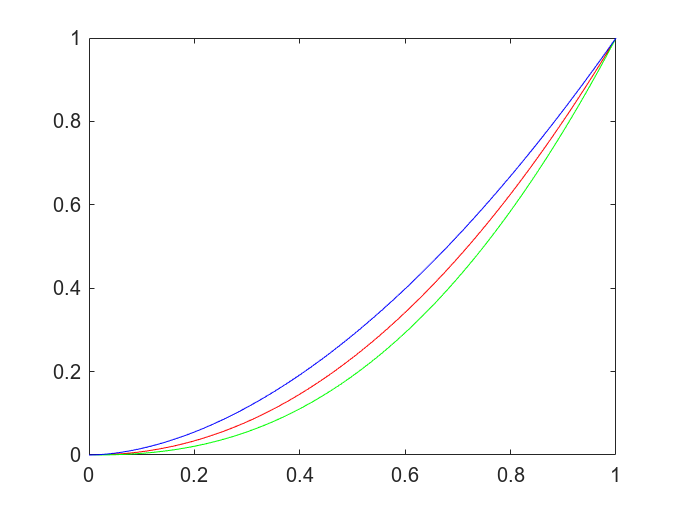

% 1.1
load("TRC_display.mat")

range = 0:0.01:1;

plot(range, TRCr, 'r')
hold on
plot(range, TRCg, 'g')
plot(range, TRCb, 'b')
hold off

**Answer:** As the blue curve has higher values than the other colors, the neutral colors will lean more towards a blueish tone.

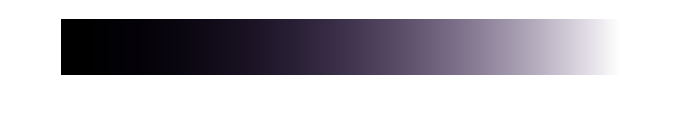

% 1.2
load("Ramp_display.mat")
load("Ramp_linear.mat")

imshow(Ramp_display)

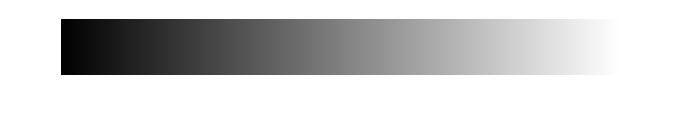

imshow(Ramp_linear)

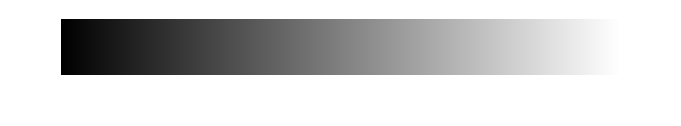


% Combine the TRC channels into the same matrix
TRC = cat(3, TRCr, TRCg, TRCb);

imshow(linearization(Ramp_display, range, TRC))

% 1.3
gammaRGB = [2.1, 2.4, 1.8];

imshow(gammaCorrection(Ramp_display, gammaRGB))

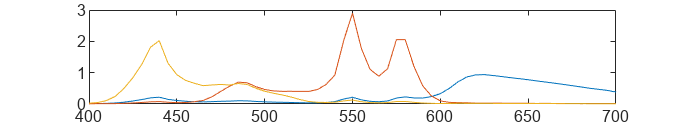

% 2.1
load("DLP.mat")

wavelength = 400:5:700;

plot(wavelength, DLP)

Answer: ?

% 2.2
load("RGB_raw.mat")

%SRGB8 = RGB_raw(1,8)*DLP(:,1) + RGB_raw(2,8)*DLP(:,2) + RGB_raw(3,8)*DLP(:,3);
SRGB8 = DLP*RGB_raw(:,8);